# 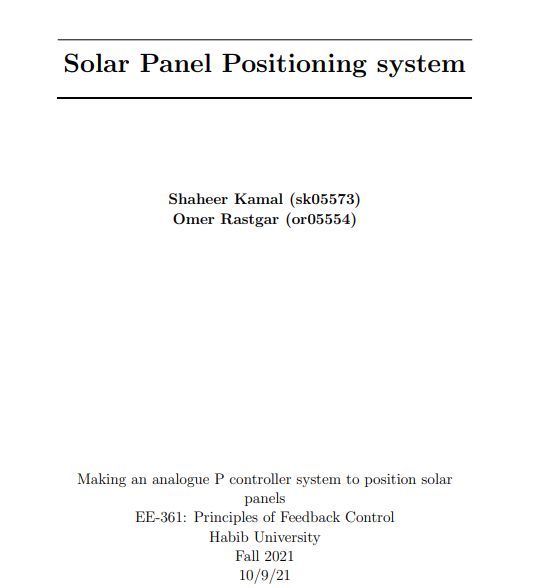

# Introduction

The aim of this project is to design a solar panel positioning system.They are usually used where less space is provided for the solar panels and no more additional panels can be added to increase the output.

 We will use a servo mechanism to adjust the current panels to make sure that they are always facing the Sun. This type of motion can be done in two axes where two motors are used to adjust the East-West direction and North-South direction. We will just be using one motor to adjust the East-West Direction.

It consists of a wooden structure which adjusts its position based on the current light intensity. Light Dependant Resistors i.e LDRs are used as sensors for the project that have a high resistance in darkness and the least resistance in high light intensity.

 The project serves as a basic framework for large scale applications in the power generation through solar energy where such a mechanism could act as a control system to adjust the position of big solar cells for maximum efficiency.

# Methods and Materials

## 2.1 Design and Fabrication of Plant 

The structure is entirely wooden. Two uniform wooden pieces are placed vertically on the base. A PVC pipe is attached to these wooden pieces through holes in the wooden walls and acts as a shaft for rotation.Another wooden frame is mounted on the shaft (PVC pipe) which acts a platform where the solar panel is to be placed. Two LDRs are also placed on this frame equidistant from the center.

## 2.2 Sketch of the Mechanical Structure 

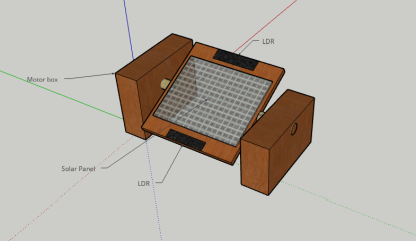

# Hardware provided 

# Motor Modeling 

## **Finding Motor constant** 

Resistance measured by DMM

R_a = 83.2 ; % ohms  



Inductance measured by inductance meter

L = 30 * 10^-3; % H

Va = 12 ; % V operating voltage
Ia= 0.02; % A


Speed found by recording the motion of the motor using a video camera and counting revolution in a min

W = 57  * (2*pi/60) / 70 % Rad/s  

W = 0.0853

using eq Va = Ia * Ra + Kt * W

kt = (Va-Ia*R_a)/W 

kt = 121.2124

km = kt

km = 121.2124

## **Finding Damping coeffiecent**

kt*Ia = B*W

B = (kt*Ia)/W % damping coeffiecent

B = 28.4297

## **Finding  Motor Interia **

**Using motor coupling:**

63% of  steady state voltage for coupled motor is 21.42V (from oscilloscope)

Time shown at steady state value :

so, Tau = 110ms (from oscilloscope) 

Tau = J*R_a/(kt*km)

 Tau = 110e-3; % seconds
 J = (Tau*kt*km)/R_a % motor inertia

J = 19.4251

## **Finding  moment of inertia of plank **

b = 0.38*10^(-2); % m breath 
h= 0.48*10^(-2); % m lenghto

j= 1/12 * 0.009 * (b^2 + h^2)

j = 2.8110e-08

## Compound Inertia

jc= j +J % compund inertia

jc = 19.4251

## Finding the rtransfer function:

T(s)  = (Kt/J*Ra/ (s+(BRa +(Kt^2/J*Ra)))

Num = kt/(jc*R_a); % numerator of the transfer function
a = (B*R_a + kt^2)/jc*R_a; 
Den = [1,a]; % denominator of transfer function
trans_func = tf(Num,Den) % transfer function of the motor

trans_func =
 
     0.075
  ------------
  s + 7.306e04
 
Continuous-time transfer function.




% W = output(Va)



M = tf(kt , [jc*L L*B+jc*R_a+R_a*B kt^2]) 

M =
 
              121.2
  ------------------------------
  0.5828 s^2 + 3982 s + 1.469e04
 
Continuous-time transfer function.



# Sensor Modeling

## **LDR modling **

t= 1.5425:0.1:4.7

t =     1.5425    1.6425    1.7425    1.8425    1.9425    2.0425    2.1425    2.2425    2.3425    2.4425    2.5425    2.6425    2.7425    2.8425    2.9425    3.0425    3.1425    3.2425    3.3425    3.4425    3.5425    3.6425    3.7425    3.8425    3.9425    4.0425    4.1425    4.2425    4.3425    4.4425    4.5425    4.6425


light_intensity= sin(t)

light_intensity =     0.9996    0.9974    0.9853    0.9633    0.9317    0.8908    0.8410    0.7828    0.7167    0.6435    0.5639    0.4786    0.3886    0.2947    0.1978    0.0989   -0.0009   -0.1007   -0.1996   -0.2964   -0.3903   -0.4802   -0.5654   -0.6449   -0.7180   -0.7839   -0.8420   -0.8916   -0.9324   -0.9638   -0.9856   -0.9976




Resistance= abs(120*sin(t))

Resistance =   119.9520  119.6916  118.2354  115.5978  111.8052  106.8955  100.9176   93.9315   86.0068   77.2228   67.6672   57.4355   46.6299   35.3584   23.7336   11.8717    0.1089   12.0883   23.9470   35.5664   46.8305   57.6266   67.8469   77.3894   86.1586   94.0669  101.0353  106.9942  111.8841  115.6561  118.2724  119.7071


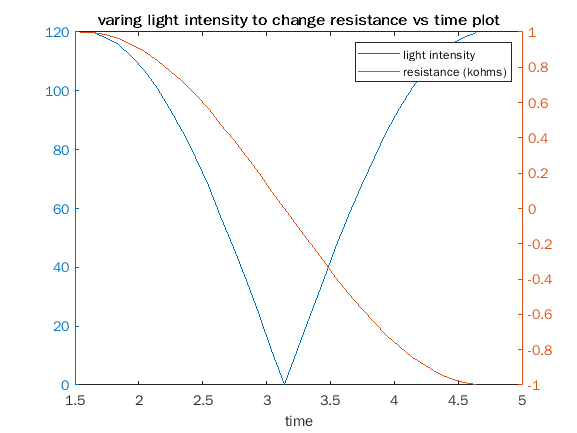


yyaxis right
plot(t,light_intensity)

yyaxis left
plot(t,Resistance)

title("varing light intensity to change resistance vs time plot")
xlabel ("time")
legend ("light intensity" , "resistance (kohms)")

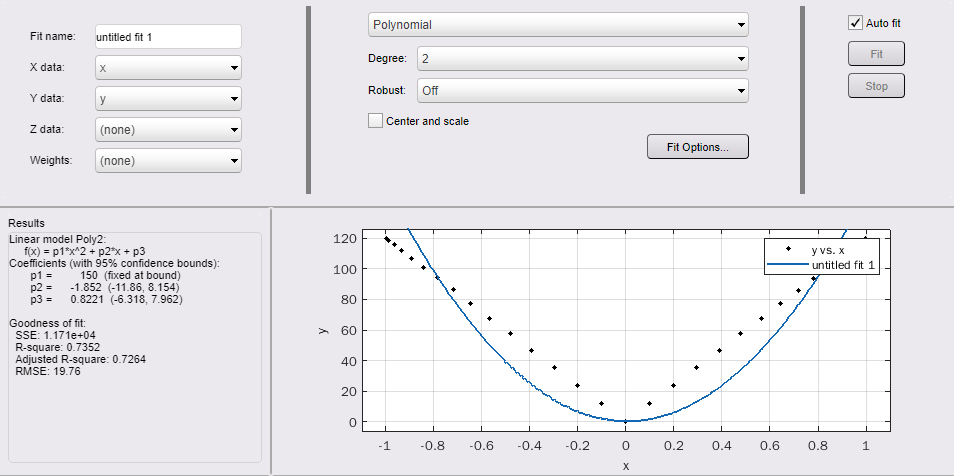

We are using polynomial for curve fitting and we have added limits in order for it to start from zero resistance and scale upwards. Since the measurments can never be fully accurate the resut we get which is exponentially increasing resistance when light comes near the sensor. hence we can conclude this to be an approximation.

 p1 =         150  

p1 = 150

 p2 =      -1.852  

p2 = -1.8520

 p3 =      0.8221

p3 = 0.8221

Resistance1 = p1*light_intensity.^2 + p2*light_intensity + p3

Resistance1 =   148.8508  148.2050  144.6183  138.2344  129.3091  118.1998  105.3518   91.2800   76.5486   61.7487   47.4741   34.2985   22.7519   13.2995    6.3234    2.1070    0.8239    2.5308    7.1652   14.5478   24.3896   36.3034   49.8193   64.4031   79.4778   94.4465  108.7161  121.7209  132.9452  141.9438  148.3596  151.9381


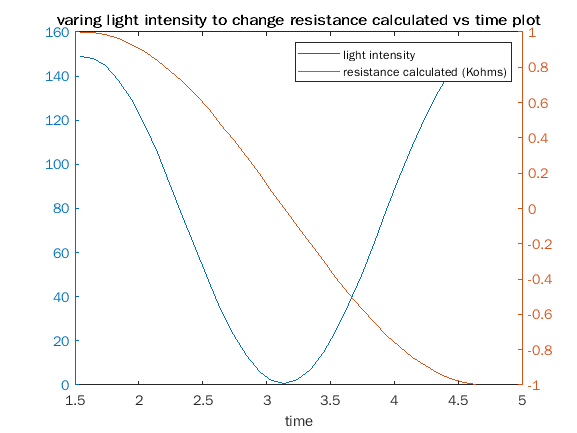


figure
yyaxis right
plot(t,light_intensity)

yyaxis left
plot(t,Resistance1)

title("varing light intensity to change resistance calculated vs time plot")
xlabel ("time")
legend ("light intensity" , "resistance calculated (Kohms)") 

## **Voltage divider Modeling**

Getting values from experimetation. we will take measurements with different light contidion to vary the resistance hence changing the voltage for one ldr.



v= [0.505	1.68	4.14  4.35 5.418	5.54	8.927]

v =     0.5050    1.6800    4.1400    4.3500    5.4180    5.5400    8.9270



r=[0.54	1.2	4.7  4.91	5.053	5.34	120]

r =     0.5400    1.2000    4.7000    4.9100    5.0530    5.3400  120.0000


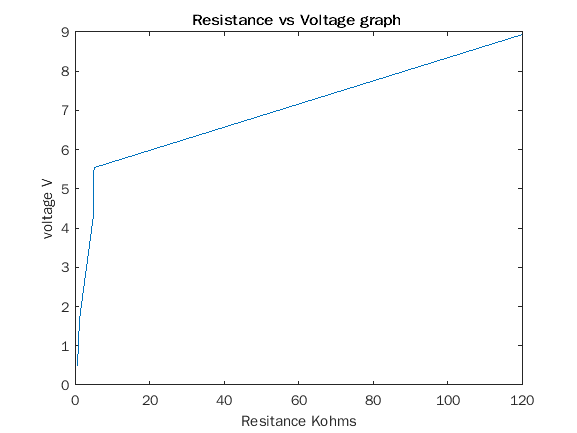

figure
plot(r,v)
title("Resistance vs Voltage graph ")
xlabel("Resitance Kohms")
ylabel ("voltage V")

#### **Curve Fitting**

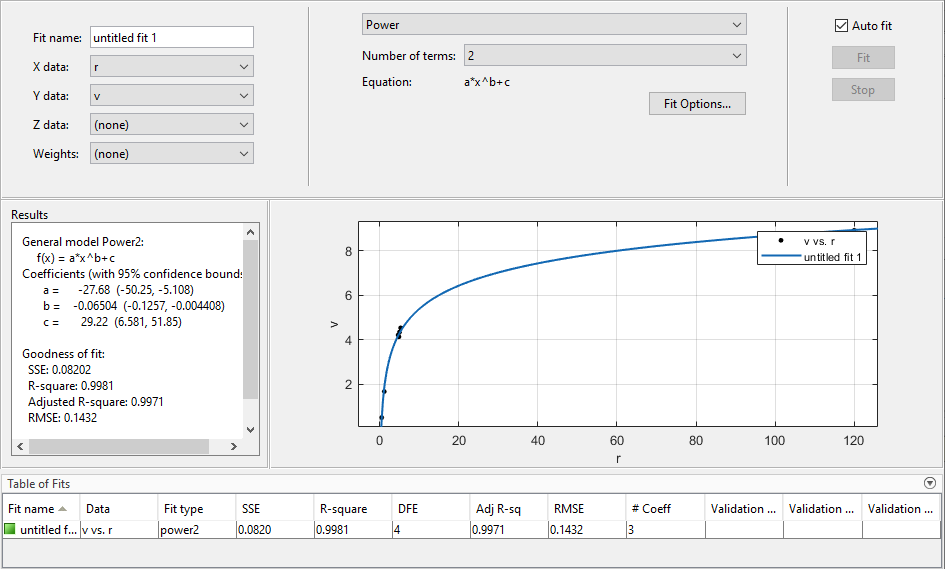

a =      -27.68;
b =    -0.06504;
c =       29.22;


v3=a*Resistance1.^b+c % the resistance calsulated in LDR modeling

v3 =     9.2283    9.2226    9.1907    9.1318    9.0444    8.9262    8.7738    8.5822    8.3446    8.0508    7.6858    7.2256    6.6305    5.8278    4.6688    2.8497    1.1891    3.1622    4.8676    5.9639    6.7324    7.3067    7.7532    8.1087    8.3955    8.6279    8.8155    8.9649    9.0808    9.1664    9.2240    9.2549


v0 = 11;
v1= (Resistance1.*v0)./(Resistance1+10) % if we use the voltage divider formula

v1 =    10.3075   10.3047   10.2886   10.2579   10.2104   10.1420   10.0464    9.9139    9.7290    9.4669    9.0861    8.5168    7.6414    6.2789    4.2612    1.9143    0.8373    2.2217    4.5917    6.5189    7.8014    8.6244    9.1611    9.5216    9.7706    9.9468   10.0734   10.1649   10.2305   10.2760   10.3054   10.3207


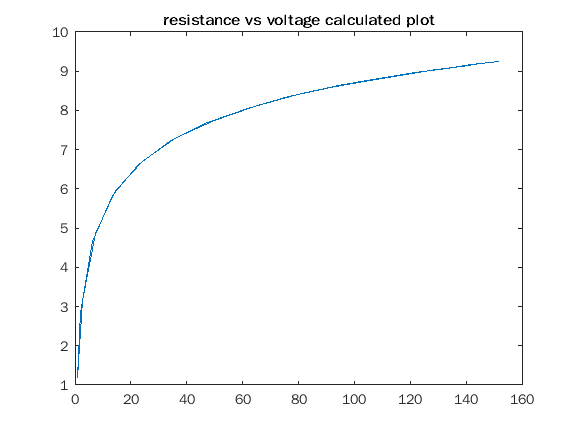




figure 
plot(Resistance1,v3)
title("resistance vs voltage calculated plot")

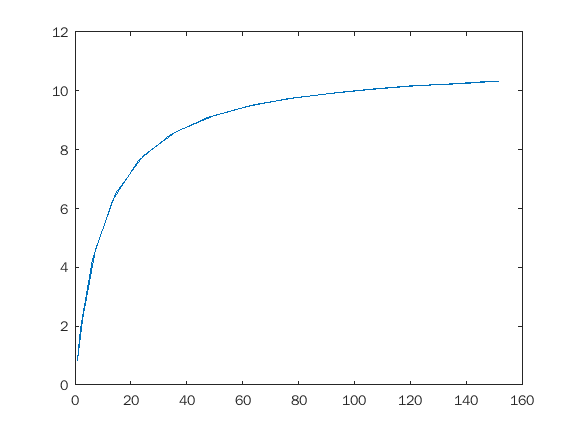

figure
title("plot taken out using voltage divider")
plot(Resistance1,v1)

Now we will use two LDR with seperate voltage dividers, which will be connected in series. Since they will be in opposit polarity it will subtract hence we will get max negative voltage or max possitive voltage when one side is in the dark 

# Block diagrams

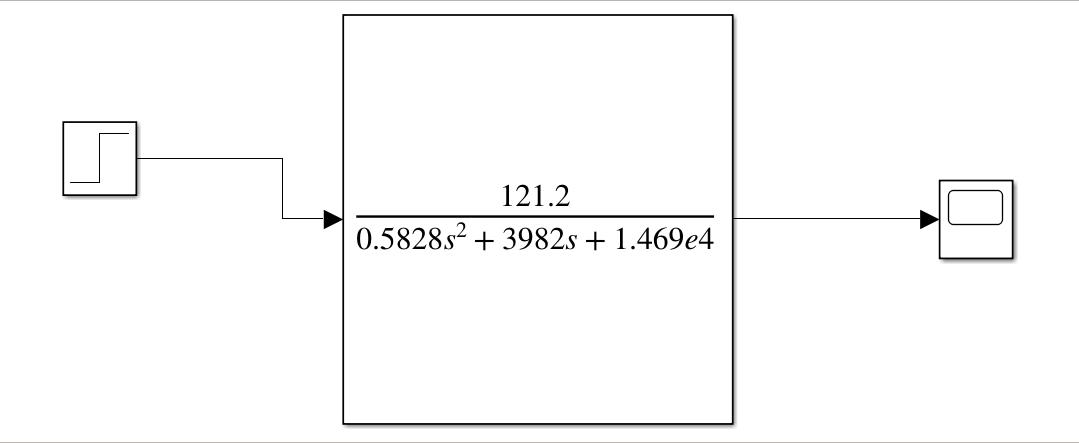

Motor transfer function

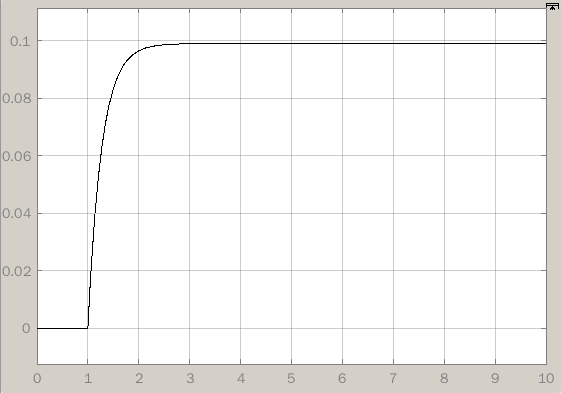

Motor speed graph, we can see that we get 0.95 Rads/sec which is close to the speed of 57 rpm that we had measured.

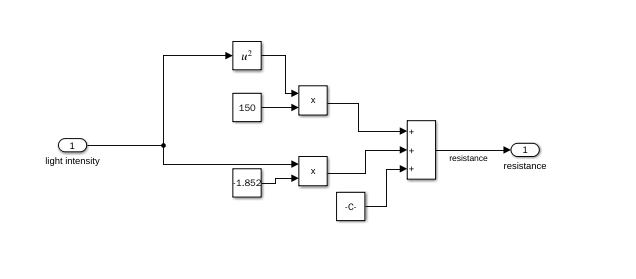

LDR Model in block diagram 

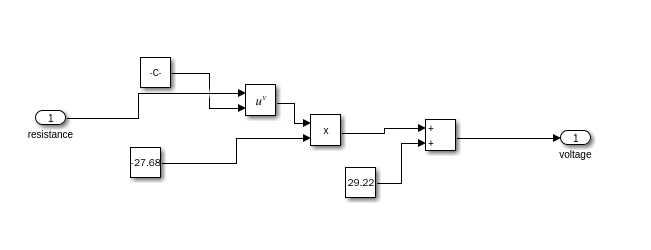

Voltage Model in block diagram 

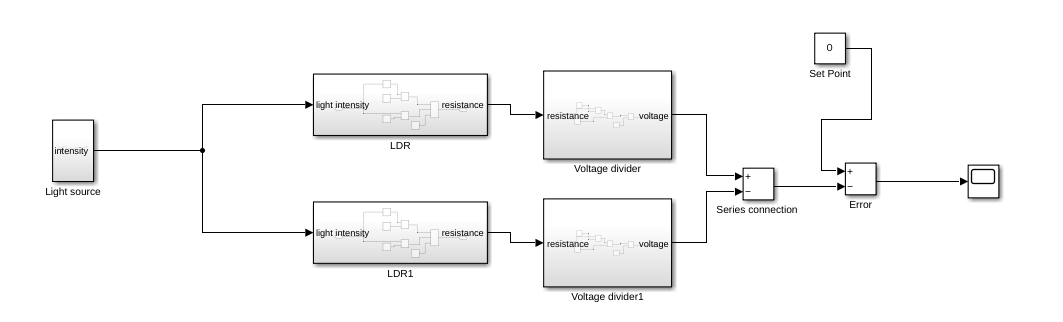

sensor in block diagram 

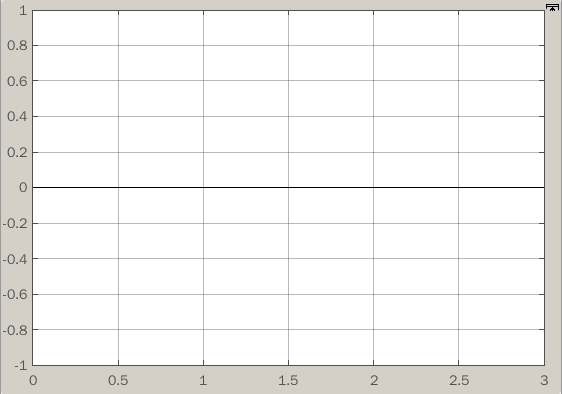

error(volts) generated when both sensors are at the same place and the light moves from left to right. there is zero error as they both have same voltage levels when  the light is moving so even tho there resistances are changing they are chnaging for both ldr hence the voltage level after subtraction is zero.

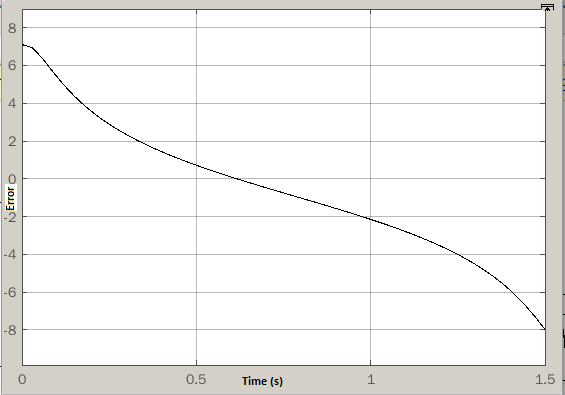

this is obtained when the LDR are placed at different ends and the light is brought closer from one end to the other. Hence we have zero error(volts) at the center where the light source is perpendicular.

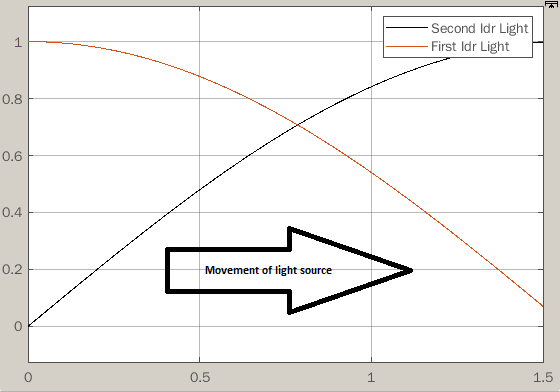

this graph shows the light intensity at the sensors at a particular time. we see tha the light source moves from LDR1 to LDR2. in the middle the light intensity is equal for both ldr as it is equvidistant from them.